GradPos -> GradC

% Init c
UNI_B_MAT = [1, 4, 1, 0;
            -3, 0, 3, 0;
            3, -6, 3, 0;
            -1, 3, -3, 1]/6;
Knot = [0,0,0;
        0,1,0;
        1,1,0;
        1,0,0];
C = (UNI_B_MAT * Knot)

C =     0.1667    0.8333         0
    0.5000    0.5000         0
    0.5000   -0.5000         0
   -0.3333         0         0


% Vis
figure; hold on;
ts = 0:0.01:1;
t_vec = [ones(size(ts)); ts; ts.^2; ts.^3];
points = C'*t_vec;
plot3(points(1,:), points(2,:),points(3,:), LineWidth=1.5);
% axis([0,1,0,1,0,1]);
axis equal;
grid on;

% PosGrad
tn = 0.19;
Gp = [-1;1;0];
beta = [1; tn; tn^2; tn^3];
gradC = beta*Gp'

gradC =    -1.0000    1.0000         0
   -0.1900    0.1900         0
   -0.0361    0.0361         0
   -0.0069    0.0069         0


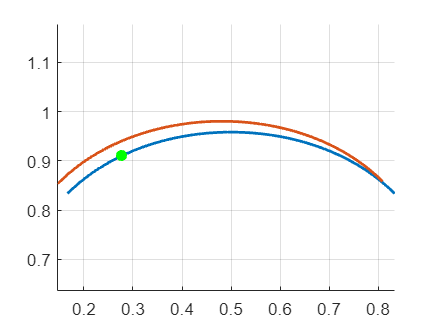

delta = 0.02;
points = (C + delta*gradC)' * t_vec;
plot3(points(1,:), points(2,:),points(3,:), LineWidth=1.5);
pt_now = C'*beta;
scatter3(pt_now(1),pt_now(2),pt_now(3), ...
    'filled', MarkerFaceColor='green');

Motor

theta_e = 0.48;
I = 1;
R = 2;
ia = I*sin(theta_e);
ib = I*sin(theta_e-deg2rad(120));
ic = I*sin(theta_e-deg2rad(240));

Wr= (ia^2+ib^2+ic^2)*R

Wr = 3.0000

Pinv

J = [1, 0, 0;
    0, 0 , 0;
    0, 0, 0];
J*J'

ans =      1     0     0
     0     0     0
     0     0     0


Jinv = J' * inv(J*J')

Jinv =      1   NaN   NaN
     0   NaN   NaN
     0   NaN   NaN


% Jinv = inv(J*J')*J'
% Jinv*J

% J'*J
% J*J'
% inv(J*J')*J'*J



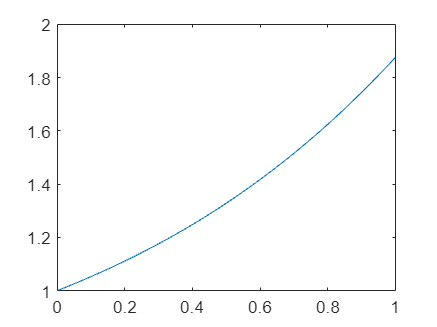

tn =0.5;
t = 0:0.01:1;
f = 1+tn*t+tn^2*t.^2+tn^3*t.^3;
plot(t, f);